clc; close all; clear all;

%% =============================================
%  PARAMETERS
%% =============================================
p.m = 0.1;
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;

J_true = 8.9432e-4;

%% =============================================
%  BUILD MODEL: No Friction (b = 0)
%% =============================================
alpha = p.m + p.M - (p.m^2 * p.l^2) / (J_true + p.m * p.l^2);
beta  = (J_true + p.m * p.l^2) - (p.m^2 * p.l^2) / (p.m + p.M);

A = [0 1 0 0;
     0, 0, -(p.m^2 * p.l^2 * p.g)/(alpha*(J_true + p.m*p.l^2)), 0;
     0 0 0 1;
     0, 0,  (p.m * p.g * p.l)/beta, 0];

B = [0; 1/alpha; 0; -(p.m*p.l)/beta*(p.m+p.M)];
C = [1 0 0 0; 0 0 1 0];
D = [0; 0];

sys_no_friction = ss(A, B, C, D);

%% =============================================
%  LOAD MEASURED DATA
%% =============================================
data = readmatrix('data.csv');

Ts        = data(2,1) - data(1,1);
time_meas = data(1:300, 1);

angle_20 = deg2rad(data(1:300, 3));
angle_50 = deg2rad(data(1:300, 6));
angle_80 = deg2rad(data(1:300, 9));

pwm_vals   = [20, 50, 80];
meas_theta = {angle_20, angle_50, angle_80};
colors     = {'b', 'r', [0.1 0.6 0.1]};

t_meas = time_meas;
Ts_sim = 0.001;
t_sim  = (t_meas(1) : Ts_sim : t_meas(end))';

%% =============================================
%  PARAMETER ESTIMATION (FRICTION b)
%% =============================================
b_guess = 0.1;
options = optimset('Display', 'iter', 'TolX', 1e-4);

best_b = fminsearch(@(b) cost_function(b, p, J_true, t_meas, meas_theta{1}, Ts_sim), ...
                    b_guess, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1            0.223         
     1            2            0.223         initial simplex
     2            4         0.222829         expand
     3            6         0.222483         expand
     4            8         0.221779         expand
     5           10         0.220198         expand
     6           12         0.216078         expand
     7           14         0.198701         expand
     8           16         0.156303         expand
     9           18         0.141944         expand
    10           20         0.132519         expand
    11           22         0.128686         expand
    12           24         0.128092         expand
    13           26         0.128092         contract outside
    14           28         0.128092         contract inside
    15           30         0.128092         contract inside
    16           32         0.128092         contract inside
    17           34


fprintf('\nOptimized Friction Coefficient b: %.4f\n', best_b);


Optimized Friction Coefficient b: -20.7120




%% =============================================
%  SIMULATE & PLOT COMPARISON
%% =============================================
fprintf('\n====== RMSE Summary ======\n');


====== RMSE Summary ======


fprintf('%-10s %-20s\n', 'PWM', 'RMSE (b=0)');

PWM        RMSE (b=0)          


fprintf('%s\n', repmat('-', 1, 32));

--------------------------------



for i = 1:3
    N     = length(t_meas);
    Y_fft = abs(fft(meas_theta{i}));
    Y_fft(1) = 0;
    half_N    = floor(N/2);
    Y_half    = Y_fft(1:half_N);
    f_vec     = (0:half_N-1) / (N * Ts);
    [~, idx]  = max(Y_half);
    omega_est = 2 * pi * f_vec(idx);

    fprintf('PWM %d — Estimated freq: %.4f Hz (%.4f rad/s)\n', ...
            pwm_vals(i), f_vec(idx), omega_est);

    u_unit      = sin(omega_est * t_sim);
    y_unit      = lsim(sys_no_friction, u_unit, t_sim);
    theta_unit  = interp1(t_sim, y_unit(:,2), t_meas);
    scale       = max(abs(meas_theta{i})) / max(abs(theta_unit));
    theta_model = scale * theta_unit;

    fprintf('PWM %d — scale (b=0): %.4f\n', pwm_vals(i), scale);
    rmse = rad2deg(sqrt(mean((meas_theta{i} - theta_model).^2)));
    fprintf('%-10d %-20.4f\n', pwm_vals(i), rmse);

    subplot(3,1,i);
    plot(t_meas, rad2deg(meas_theta{i}), 'k',  'LineWidth', 2.0, 'DisplayName', 'Measured'); hold on;
    plot(t_meas, rad2deg(theta_model),   '--', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Model (b=0), RMSE=%.4f deg', rmse));
    title(sprintf('Pendulum Angle \\theta — PWM = %d', pwm_vals(i)));
    xlabel('Time (s)'); ylabel('\theta (deg)');
    legend('Location', 'best'); grid on;
    ylim([-200 200]);
end

PWM 20 — Estimated freq: 1.3333 Hz (8.3776 rad/s)


PWM 20 — scale (b=0): 0.5906


20         12.6759             


PWM 50 — Estimated freq: 0.3333 Hz (2.0944 rad/s)


PWM 50 — scale (b=0): 8.9177


50         23.5695             


PWM 80 — Estimated freq: 0.3333 Hz (2.0944 rad/s)


PWM 80 — scale (b=0): 43.5064


80         114.9719            


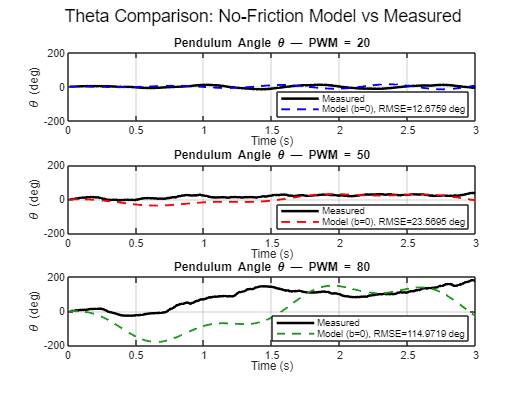


sgtitle('Theta Comparison: No-Friction Model vs Measured');


%% =============================================
%  COST FUNCTION
%% =============================================
function total_error = cost_function(b, p, J_true, t_meas, theta_meas, Ts_sim)
    M_total = p.m + p.M;
    L_p     = J_true + p.m * p.l^2;
    det_val = M_total * L_p - (p.m * p.l)^2;

    A = [0 1 0 0;
         0, -b*L_p/det_val,          -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  b*p.m*p.l/det_val,       (p.m*p.g*p.l*M_total)/det_val, 0];

    B = [0; L_p/det_val; 0; -p.m*p.l/det_val];
    C = [1 0 0 0; 0 0 1 0];
    D = [0; 0];

    sys_temp = ss(A, B, C, D);

    t_sim = (t_meas(1) : Ts_sim : t_meas(end))';

    % Estimate frequency from measured data
    N     = length(t_meas);
    Ts    = t_meas(2) - t_meas(1);
    Y_fft = abs(fft(theta_meas));
    Y_fft(1) = 0;
    half_N    = floor(N/2);
    [~, idx]  = max(Y_fft(1:half_N));
    f_vec     = (0:half_N-1) / (N * Ts);
    omega_est = 2 * pi * f_vec(idx);

    u = sin(omega_est * t_sim);
    y = lsim(sys_temp, u, t_sim);

    theta_model = interp1(t_sim, y(:,2), t_meas);
    scale       = max(abs(theta_meas)) / max(abs(theta_model));
    error_vec   = theta_meas - (scale * theta_model);
    total_error = sqrt(mean(error_vec.^2));
end


clc; close all; clear all;

%% =============================================
%  PARAMETERS
%% =============================================
p.m = 0.1;
p.M = 0.427;
p.l = 0.10382;
p.g = -9.81;

J_true = 8.9432e-4;

% Known drive frequency from MicroPython (delay = 0.5s → period = 1s)
f_drive     = 1 / 0.2;
omega_drive = 2 * pi * f_drive;

%% =============================================
%  LOAD MEASURED DATA
%% =============================================
data = readmatrix('data.csv');

Ts        = data(2,1) - data(1,1);
time_meas = data(1:300, 1);

angle_20 = deg2rad(data(1:300, 3));
angle_50 = deg2rad(data(1:300, 6));
angle_80 = deg2rad(data(1:300, 9));

pwm_vals   = [20, 50, 80];
meas_theta = {angle_20, angle_50, angle_80};
colors     = {'b', 'r', [0.1 0.6 0.1]};

t_meas = time_meas;
Ts_sim = 0.001;
t_sim  = (t_meas(1) : Ts_sim : t_meas(end))';

%% =============================================
%  OPTIMIZE b ONLY (using PWM=20 data)
%% =============================================
b_guess = 0.1;
options = optimset('Display', 'iter', 'TolX', 1e-6, 'TolFun', 1e-6, 'MaxIter', 1000);

best_b = fminsearch(@(b) cost_function_b(b, p, J_true, t_meas, meas_theta{1}, Ts_sim, omega_drive), ...
                    b_guess, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1         0.273669         
     1            2          0.27364         initial simplex
     2            4         0.273591         expand
     3            6         0.273524         expand
     4            8         0.273247         expand
     5           10         0.272739         expand
     6           12         0.270404         expand
     7           14         0.266457         expand
     8           16         0.263687         expand
     9           18         0.263687         contract outside
    10           20         0.263622         contract inside
    11           22         0.263622         contract inside
    12           24         0.263617         contract inside
    13           26         0.263617         contract inside
    14           28         0.263617         contract inside
    15           30         0.263617         contract inside
    16           32         0.263617        


fprintf('\n====== Optimization Results ======\n');


====== Optimization Results ======


fprintf('Friction b : %.4f\n', best_b);

Friction b : 1.4999



%% =============================================
%  BUILD MODEL WITH OPTIMIZED b
%% =============================================
M_total = p.m + p.M;
L_p     = J_true + p.m * p.l^2;
det_val = M_total * L_p - (p.m * p.l)^2;

A_opt = [0 1 0 0;
         0, -best_b*L_p/det_val,       -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  best_b*p.m*p.l/det_val,    (p.m*p.g*p.l*M_total)/det_val, 0];

B_opt = [0; L_p/det_val; 0; -p.m*p.l/det_val];
C_mat = [1 0 0 0; 0 0 1 0];
D_mat = [0; 0];

sys_opt = ss(A_opt, B_opt, C_mat, D_mat);

%% =============================================
%  SIMULATE & PLOT
%% =============================================
fprintf('\n====== RMSE Summary ======\n');


====== RMSE Summary ======


fprintf('%-10s %-20s\n', 'PWM', 'RMSE (b optimized)');

PWM        RMSE (b optimized)  


fprintf('%s\n', repmat('-', 1, 32));

--------------------------------



figure;
for i = 1:3
    % Square wave input scaled by PWM value
    u           = pwm_vals(i) * sign(sin(omega_drive * t_sim));
    y           = lsim(sys_opt, u, t_sim);
    theta_model = interp1(t_sim, y(:,2), t_meas);

    % Amplitude scale to account for PWM-to-force gain (unknown hardware constant)
    scale       = max(abs(meas_theta{i})) / max(abs(theta_model));
    theta_scaled = scale * theta_model;

    rmse = rad2deg(sqrt(mean((meas_theta{i} - theta_scaled).^2)));
    fprintf('%-10d %-20.4f\n', pwm_vals(i), rmse);

    subplot(3,1,i);
    plot(t_meas, rad2deg(meas_theta{i}),  'k',  'LineWidth', 2.0, ...
         'DisplayName', 'Measured'); hold on;
    plot(t_meas, rad2deg(theta_scaled),   '--', 'Color', colors{i}, 'LineWidth', 1.5, ...
         'DisplayName', sprintf('Model (b=%.4f), RMSE=%.4f deg', best_b, rmse));
    title(sprintf('Pendulum Angle \\theta — PWM = %d', pwm_vals(i)));
    xlabel('Time (s)'); ylabel('\theta (deg)');
    legend('Location', 'best'); grid on;
    ylim([-100 100]);
end

20         15.1041             
50         29.6431             
80         143.5252            


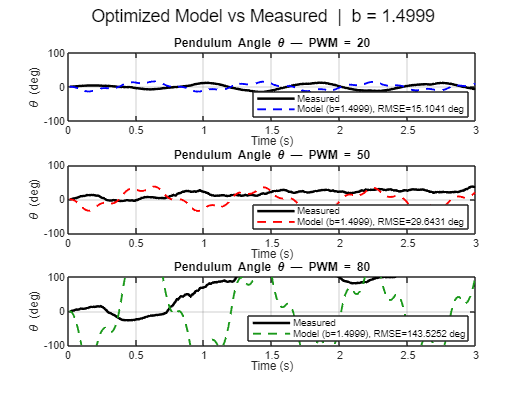


sgtitle(sprintf('Optimized Model vs Measured  |  b = %.4f', best_b));

Starting optimization...


 
 Iteration   Func-count         f(x)         Procedure
     0            1          3.20656         
     1            3          3.20651         initial simplex
     2            5          3.18205         expand
     3            6          3.18205         reflect
     4            8          3.11311         expand
     5            9          3.11311         reflect
     6           11          2.94573         expand
     7           12          2.94573         reflect
     8           14          2.81024         reflect
     9           16          2.80972         reflect
    10           18           2.7925         contract inside
    11           20          2.79211         reflect
    12           22         0.128515         contract inside
    13           23         0.128515         reflect
    14           25         0.128515         contract inside
    15           27         0.128515         contract inside
    16           29         0.128515         contract inside
    


====== Results ======


Friction b : -1.881710


Input Gain K: -0.000000


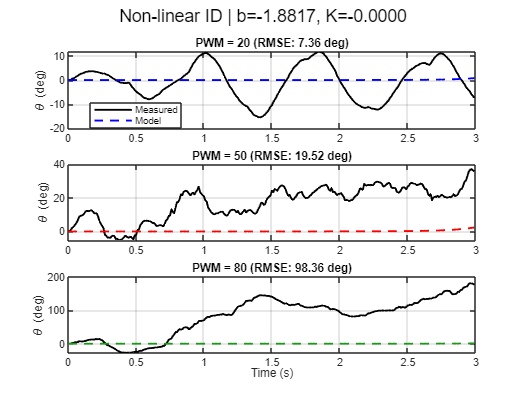

Optimizing parameters...


 
 Iteration   Func-count         f(x)         Procedure
     0            1          8.24762         
     1            3          8.24762         initial simplex
     2            5             8.11         expand
     3            7           7.8173         reflect
     4            8           7.8173         reflect
     5           12           7.8173         shrink
     6           14           7.8173         contract outside
     7           18           7.8173         shrink
     8           20           7.8173         contract outside
     9           22           7.8173         contract inside
    10           26           7.8173         shrink
    11           28           7.8173         contract outside
    12           30          7.81265         reflect
    13           32          7.81265         contract inside
    14           34          7.81265         contract inside
    15           36          7.81076         expand
    16           38          7.81076         con


====== Results ======


Friction b : 0.009238


Motor Gain K: 0.005182


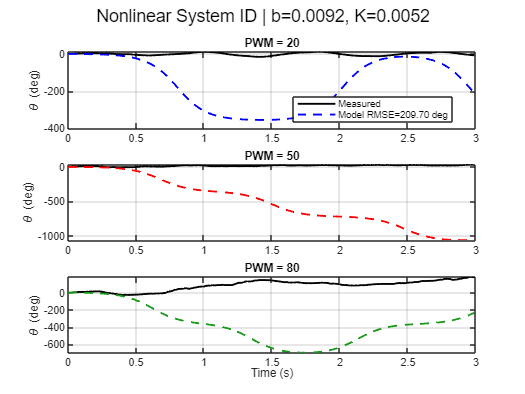


%% =============================================
%  COST FUNCTION: optimize b only
%% =============================================
function total_error = cost_function_b(b, p, J_true, t_meas, theta_meas, Ts_sim, omega_drive)
    M_total = p.m + p.M;
    L_p     = J_true + p.m * p.l^2;
    det_val = M_total * L_p - (p.m * p.l)^2;

    A = [0 1 0 0;
         0, -b*L_p/det_val,        -(p.m^2*p.l^2*p.g)/det_val, 0;
         0 0 0 1;
         0,  b*p.m*p.l/det_val,     (p.m*p.g*p.l*M_total)/det_val, 0];
    B = [0; L_p/det_val; 0; -p.m*p.l/det_val];
    C = [1 0 0 0; 0 0 1 0];
    D = [0; 0];

    sys_temp = ss(A, B, C, D);

    t_sim = (t_meas(1) : Ts_sim : t_meas(end))';
    if numel(t_sim) < 2
        total_error = 1e6; return;
    end

    u           = sign(sin(omega_drive * t_sim));   % unit square wave
    y           = lsim(sys_temp, u, t_sim);
    theta_model = interp1(t_sim, y(:,2), t_meas);

    % Scale to remove amplitude ambiguity, optimize shape/phase only
    scale       = max(abs(theta_meas)) / max(abs(theta_model));
    error_vec   = theta_meas - scale * theta_model;
    total_error = sqrt(mean(error_vec.^2));
end
